Question 1a:

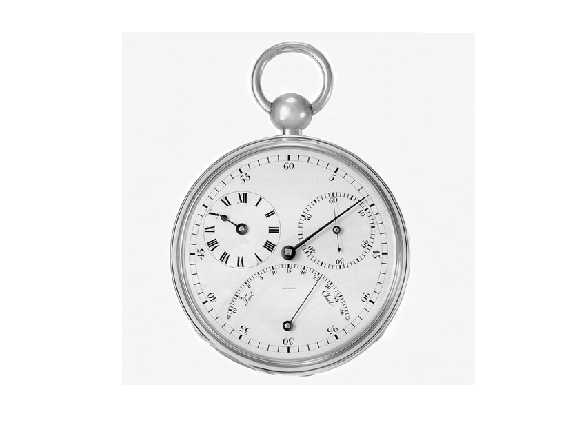

I = imread('HW4_images/HW04_input.png');

%resize image to the next powers of 2
I = im2double(imresize(I,[2^nextpow2(size(I,1)) 2^nextpow2(size(I,2))]));

figure;
imshow(I,[]);

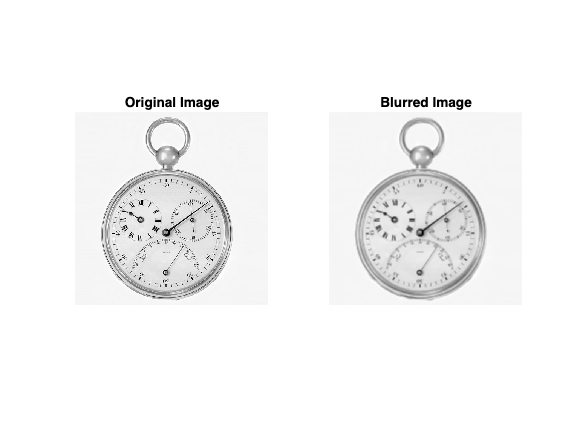

%out-of-focus blur
kernel = fspecial('average', 5);

%applying the filter
blurred_image = imfilter(I, kernel, 'symmetric');

figure;

subplot(1,2,1);
imshow(I, []);
title("Original Image");

subplot(1,2,2);
imshow(blurred_image, []);
title("Blurred Image");

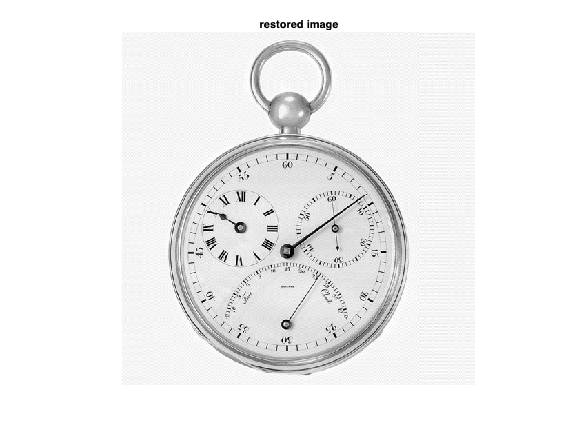

%creating DFT for the blur
kernel_dft = fft2(kernel, size(blurred_image, 1), size(blurred_image, 2));

%extracting the original image using inverse filter
original_image = real(ifft2(fft2(blurred_image) ./ kernel_dft));
original_image_restored = im2uint8(original_image);

figure;
imshow(original_image_restored);
title("restored image", FontSize=8);

Inverse filtering is essentially the exact inverse of the blurring process, so without the limitations of precision of computation it should produce an exact restoration of the original image in the absence of noise.

Question 1b:


$$\textrm{As}\;\textrm{given},\textrm{SNR}=10\;\log_{10}$$

$$\frac{P_{\textrm{ss}} }{P_{\textrm{vv}} }$$


Now Solving for $P_{\textrm{vv}}$ , we get

$P_{\textrm{vv}}$ = $\frac{P_{\textrm{ss}} }{{10}^{\frac{\textrm{SNR}}{10}} }$

Putting the values, we get,

$P_{\textrm{vv}}$ = $\frac{P_{\textrm{ss}} }{{10}^3 }$

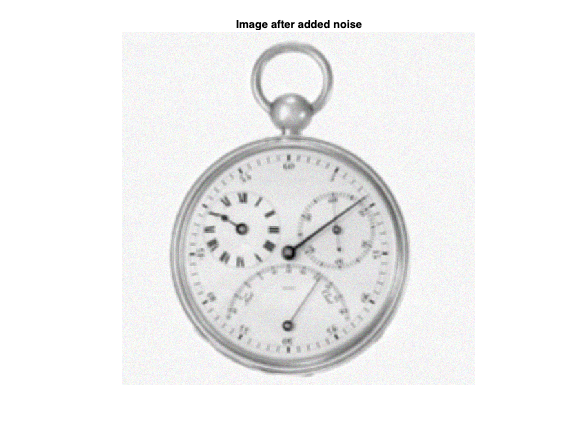

Pss = rms(blurred_image, "all") .^ 2;
Pvv = Pss / 1000;

noisy_blurred_image = imnoise(blurred_image, "gaussian", 0, Pvv);

figure;
imshow(noisy_blurred_image);
title("Image after added noise", FontSize = 8);

psnr_blurred_with_original_ref = psnr(blurred_image, I)

psnr_blurred_with_original_ref = 23.1327

psnr_noisy_blurred_with_original_ref = psnr(noisy_blurred_image, I)

psnr_noisy_blurred_with_original_ref = 22.5136

psnr_noisy_blurred_with_blurred_ref = psnr(noisy_blurred_image, blurred_image)

psnr_noisy_blurred_with_blurred_ref = 31.3286

Question 2:

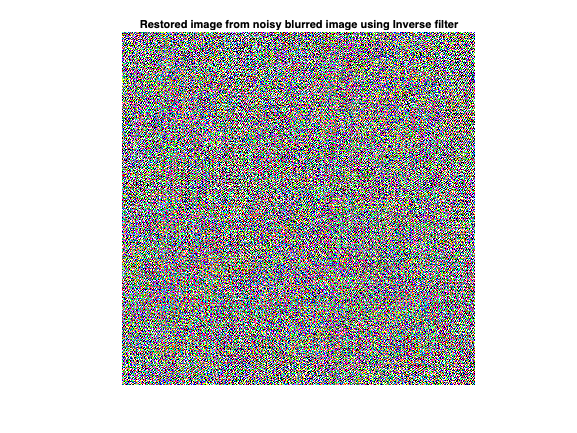

% Try restoration using Least Squares Filtering.
original_image_from_noisy_blurred = real(ifft2(fft2(noisy_blurred_image) ./ (kernel_dft + 0.001)));

figure;
imshow(original_image_from_noisy_blurred,[]);
title("Restored image from noisy blurred image using Inverse filter", FontSize=8);

Question 3:

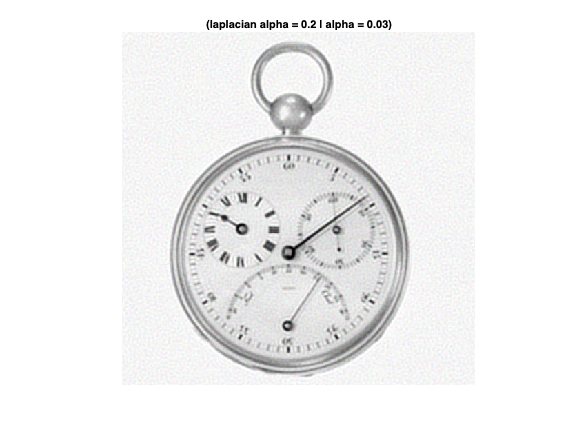

noisy_image_blurred_fft = fft2(noisy_blurred_image);
kernel_otf = psf2otf(kernel, [size(blurred_image, 1), size(blurred_image, 2)]);

% Try restoration using Least Squares Filtering.
laplacian_1 = fspecial('laplacian', 0.2);
laplacian_2 = fspecial('laplacian', 0.5);

laplacian_otf_1 = psf2otf(laplacian_1, [size(blurred_image, 1), size(blurred_image, 2)]);
laplacian_otf_2 = psf2otf(laplacian_2, [size(blurred_image, 1), size(blurred_image, 2)]);

alpha_1 = 0.03;
alpha_2 = 0.05;
alpha_3 = 0.07;

original_image_from_noisy_blurred_l1_a1 = real(ifft2(conj(kernel_otf) .* noisy_image_blurred_fft ./ (kernel_otf .^ 2 + alpha_1 * (laplacian_otf_1 .^2))));
original_image_from_noisy_blurred_l1_a2 = real(ifft2(conj(kernel_otf) .* noisy_image_blurred_fft ./ (kernel_otf .^ 2 + alpha_2 * (laplacian_otf_1 .^2))));
original_image_from_noisy_blurred_l1_a3 = real(ifft2(conj(kernel_otf) .* noisy_image_blurred_fft ./ (kernel_otf .^ 2 + alpha_3 * (laplacian_otf_1 .^2))));
original_image_from_noisy_blurred_l2_a1 = real(ifft2(conj(kernel_otf) .* noisy_image_blurred_fft ./ (kernel_otf .^ 2 + alpha_1 * (laplacian_otf_2 .^2))));
original_image_from_noisy_blurred_l2_a2 = real(ifft2(conj(kernel_otf) .* noisy_image_blurred_fft ./ (kernel_otf .^ 2 + alpha_2 * (laplacian_otf_2 .^2))));
original_image_from_noisy_blurred_l2_a3 = real(ifft2(conj(kernel_otf) .* noisy_image_blurred_fft ./ (kernel_otf .^ 2 + alpha_3 * (laplacian_otf_2 .^2))));

figure;
imshow(original_image_from_noisy_blurred_l1_a1, []);
title("(laplacian alpha = 0.2 | alpha = 0.03)", FontSize=8);

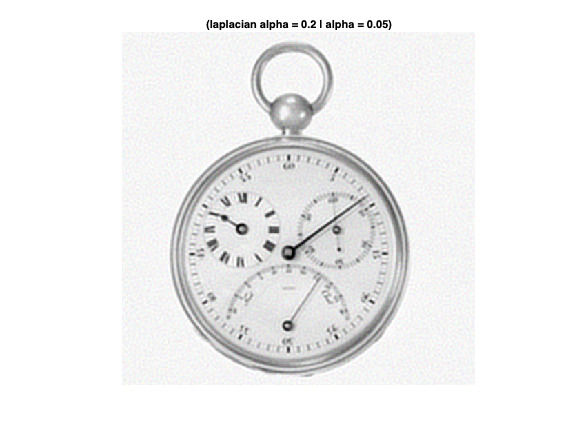


imshow(original_image_from_noisy_blurred_l1_a2, []);
title("(laplacian alpha = 0.2 | alpha = 0.05)", FontSize=8);

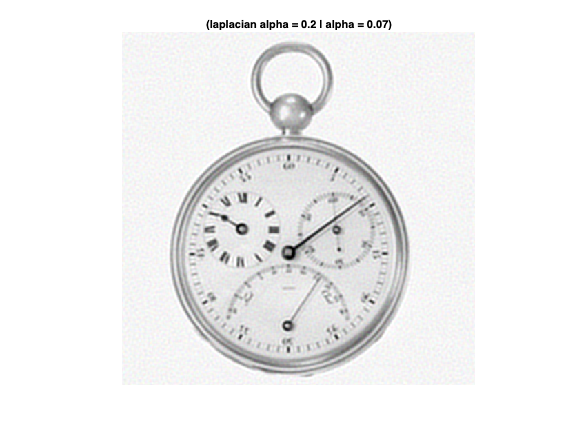


imshow(original_image_from_noisy_blurred_l1_a3, []);
title("(laplacian alpha = 0.2 | alpha = 0.07)", FontSize=8);

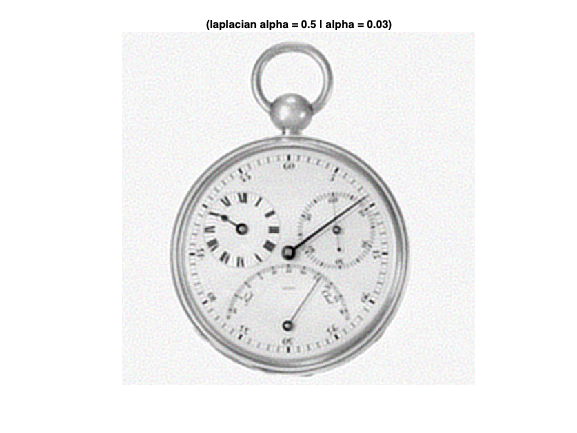


imshow(original_image_from_noisy_blurred_l2_a1, []);
title("(laplacian alpha = 0.5 | alpha = 0.03)", FontSize=8);

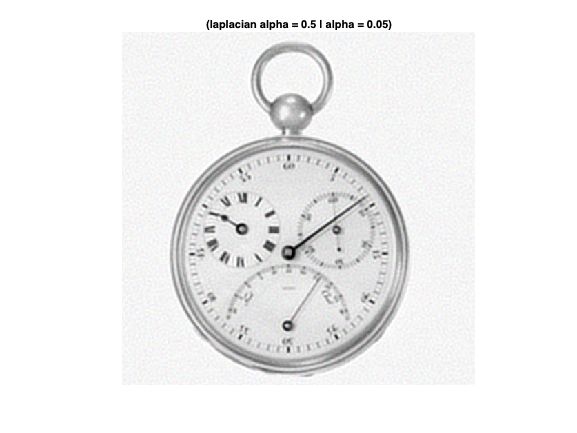


imshow(original_image_from_noisy_blurred_l2_a2, []);
title("(laplacian alpha = 0.5 | alpha = 0.05)", FontSize=8);

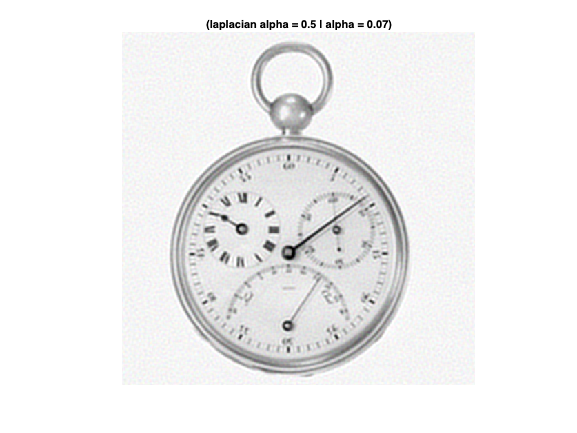


imshow(original_image_from_noisy_blurred_l2_a3, []);
title("(laplacian alpha = 0.5 | alpha = 0.07)", FontSize=8);